# Lab 7 - Surrogate Modeling

Jared Ham

**Task 1: Response Surface Modeling (RSM)**

Given a computationally intensive model, run a discrete amount of simulations and fit a surface to the outputs to allow quicker querying of the model. 

We can call the intensive model using the following the code

x = [1,1];
y = giant_CFD_code(x)

y = 3.2333

Before running the model and fitting to a surface a data set needs to be created in the domain of:


$$\begin{array}{l}
-2\le x_1 \le 2\\
-1\le x_2 \le 1
\end{array}$$


With the following constraints:

70% used for training

15% used for validation (Not neccessary for RSM, but will be for neural network).

15%(30% for RSM) used for testing

n_x1 = 10; %number of x1 data points
n_x2 = 10; % number of x2 data points

x1 = linspace(-2, 2, n_x1);
x2 = linspace(-1, 1, n_x2);

X_training = zeros(floor(n_x1*n_x2 * 0.7), 2);
X_validate = zeros(floor(n_x1 * n_x2*0.2),2);
Y_training = zeros(floor(0.6 * n_x1 * n_x2) , 1);
Y_validate = zeros(floor(n_x1 * n_x2*0.2),1);

X_training_index = 1;
X_validate_index = 1;
Y_traning_index = 1;
Y_validate_index = 1;
for i = 1:length(x1)
    for j = 1:length(x2)
        
        if(rand < 0.7)
            %this will be used in the training set
            Y_training(Y_traning_index) = giant_CFD_code([x1(i), x2(j)]);
            Y_traning_index = Y_traning_index + 1;
            
            X_training(X_training_index, 1) = x1(i);
            X_training(X_training_index, 2) = x2(j);
            X_training_index = X_training_index + 1;
        else
            %this set will be used for validation
            Y_validate(Y_validate_index) = giant_CFD_code([x1(i), x2(j)]);
            Y_validate_index = Y_validate_index + 1;
            
            X_validate(X_validate_index, 1) = x1(i);
            X_validate(X_validate_index, 2) = x2(j);
            X_validate_index = X_validate_index + 1;
        end
        
        
    end
end

Now that we have a training set and a validation set. Let's fit a response surface of the following form using MatLab's rstool


$$y=\beta_1 +\beta_2 x_1 +\beta_3 x_2 +\beta_4 x_1 x_2 +\beta_5 x_1^2 +\beta_6 x_2^2$$


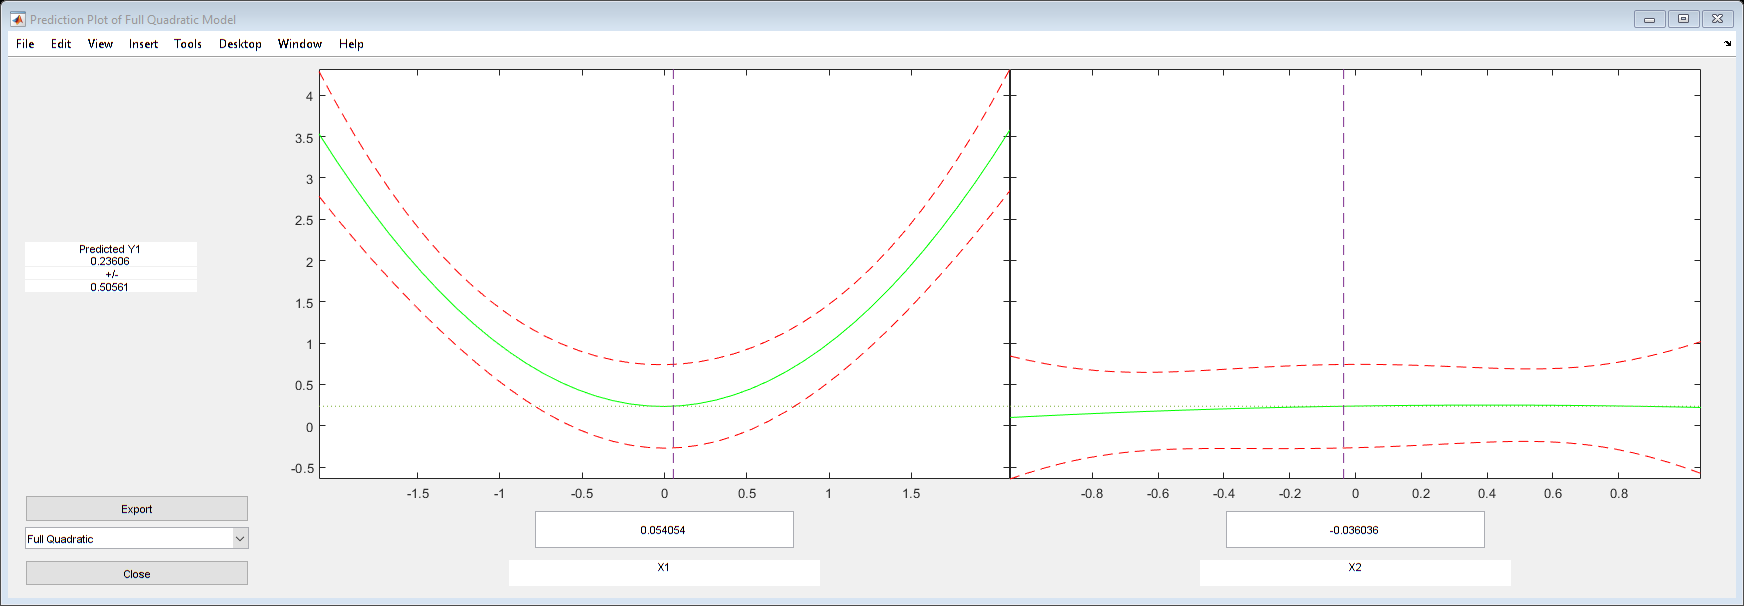

rstool(X_training, Y_training, 'quadratic')

Figure 1: rstool Plots

**Task 2 - Neural Network Surrogate Modeling**

%combine the training and validation data from RSM into one vector for use
%in the nntool
X_nn = [X_training', X_validate']';
Y_nn = [Y_training', Y_validate']';

nnstart

Regression plots for NN shown in the homework section. 

**Task 3 - Homework**

1) Provide a table to compare the characteristics of your two surrogate models on the bases of

a. Computational time required to evaluate each surrogate model 100 times

%Evaluate response surface 100 times
n = 100

n = 100

tic
for i=1:n
    RSM([4*rand - 2, 2*rand - 1], beta);
end
toc

Elapsed time is 0.008126 seconds.


%Evaluate Neural Net 100 times
tic 
for i=1:n
    sim(net,[4*rand - 2; 2*rand - 1]);
end
toc

Elapsed time is 0.508981 seconds.


b. Actual by predicted plot for each data set (training, validation and testing), use the Matlab function plotregression

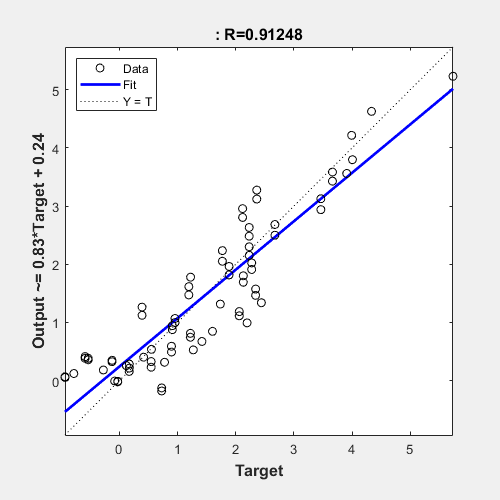

plotregression(Y_training, RSM(X_training, beta));

Figure 2: Regression Plot for the Training data of the resposnse surface

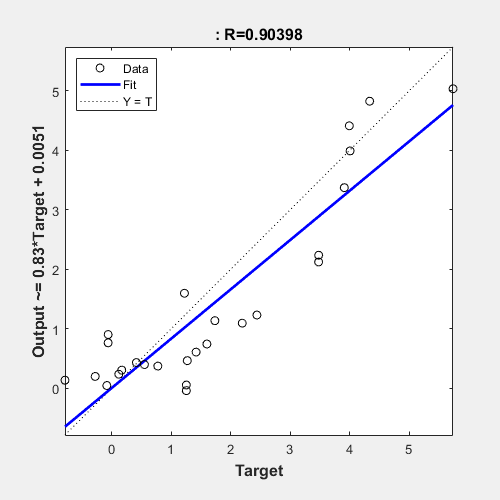

plotregression(Y_validate, RSM(X_validate, beta))

Figure 3: Regression plot for the validation data for the response surface

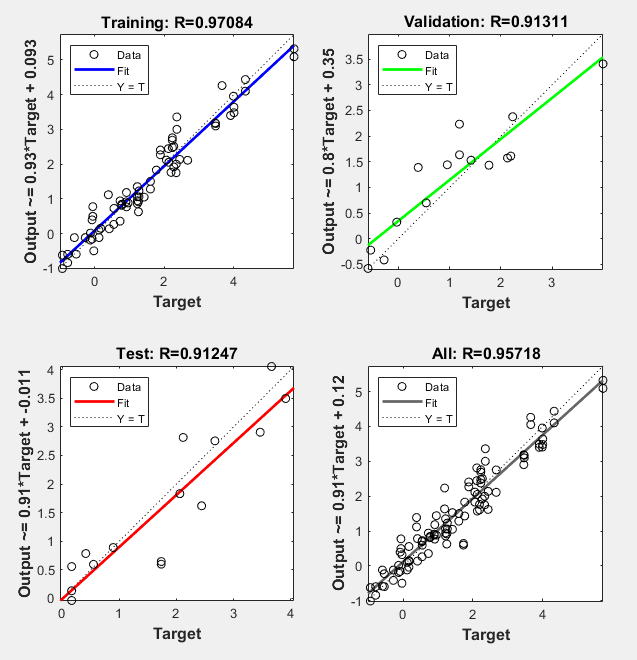

Figure 4: Regression Plots for the Neural Network Generated with nnstart

c. Average Absolute Value of Relative Error associated with your surrogate models. Which surrogate model to you prefer?

ANN_mean_error = mean(abs(error))

ANN_mean_error = 0.2095

RSM_error = mean(abs((RSM(X_nn, beta) - Y_nn) ./ Y_nn))

RSM_error = 0.8532

In the table below, the metrics for comparison of the response surface and the neural net are shown. 

As can be seen, the Neural Net is a better predictor of the actual CFD code according to the average relative error and to the regression of fit. However, though the neural net is much faster than the CFD, it is still magnitudes slower than the response surface. So if you had to evaluate the CFD hundreds of thousands or millions of choice and could live with erros on the order of 85% then the response surface might be a better choice. But for any simulations requiring data points in the thousands or less I would stick with the neural net due to its higher accuracy. 

**2) Perform a numerical optimization on your ANN surrogate-CFD model to derive the minimum value of y, as a function of x1, and x2. You may initialize your model at any of the corner points of the design space. You can run the following MATLAB code to get your optimizer to run on the actual CFD model. It may take multiple hours to get your optimization to run using the CFD code. Compare the results of this optimization to the results of the same optimization on your surrogate model (the ANN) of the CFD code.**

%optimization with the actual CFD Code
tic
options = optimset('Display','iter');
[X,FVAL] = fminsearch('giant_CFD_code',[1,1],options);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          3.23333         


     1            3          3.23333         initial simplex


     2            5          2.68435         expand


     3            7          2.31142         expand


     4            9          2.13322         expand


     5           11          2.05511         reflect


     6           13          2.05511         contract inside


     7           15           1.7418         expand
     8           16           1.7418         reflect


     9           18         0.838199         expand
    10           19         0.838199         reflect


    11           21          0.13979         expand


    12           23        -0.873345         expand


    13           25        -0.873345         contract inside


    14           27        -0.927081         reflect


    15           29        -0.961831         contract outside


    16           31         -1.00908         contract inside


    17           33         -1.02566         contract inside


    18           35         -1.02566         contract inside


    19           37          -1.0259         contract inside


    20           39         -1.02804         contract inside


    21           41         -1.03155         contract inside
    22           42         -1.03155         reflect


    23           44         -1.03155         contract inside


    24           46         -1.03155         contract outside


    25           48         -1.03155         contract inside


    26           50         -1.03156         contract outside


    27           52          -1.0316         contract inside


    28           54         -1.03161         contract inside


    29           56         -1.03162         contract outside


    30           58         -1.03162         contract inside


    31           60         -1.03163         contract inside


    32           62         -1.03163         contract inside


    33           64         -1.03163         contract outside


    34           66         -1.03163         contract inside


    35           68         -1.03163         contract inside


    36           70         -1.03163         contract outside


    37           72         -1.03163         contract inside


    38           74         -1.03163         contract inside
    39           75         -1.03163         reflect


    40           77         -1.03163         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



toc

Elapsed time is 791.665384 seconds.


%Now optimize with the ANN
fun = @(x)sim(net,[x(1),x(2)]');
tic
options = optimset('Display','iter');
[X_min_nn,FVAL_nn] = fminsearch(fun,[1,1], options);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          2.73508         
     1            3          2.73508         initial simplex
     2            5           2.2121         expand
     3            7          1.79737         expand
     4            9          1.67693         reflect
     5           11           1.3947         expand
     6           12           1.3947         reflect
     7           14           1.3947         contract outside
     8           16          1.10743         expand
     9           18           1.0724         reflect
    10           20          0.45083         expand
    11           21          0.45083         reflect
    12           23         0.431616         reflect
    13           25        -0.492772         expand
    14           27        -0.535352         reflect
    15           29         -1.01891         reflect
    16           31         -1.01891         contract inside
    17           32         -1

toc

Elapsed time is 0.481175 seconds.


X_min_nn

X_min_nn =    -0.2217    0.6963


FVAL_nn

FVAL_nn = -1.0234

The reported minimum values and the corresponding x values for each are shown in the table below. Note that the neural net surrogate model found the solution in less than a second while the full cfd solution took 740 seconds (~12 minutes). 

The neural net found function minimum value within 1% of the actual value. However the x values that the neural net predicts for the minimum values do not agree as well. X1 has an error of 145% and X2 has an error of about 2%, much better than that of x1. 

**3) Perform a **$2^2$**-DOE-based global sensitivity analysis on your ANN surrogate-CFD model at the minimum value of y, so as to calculate the sensitivity of the output y to the inputs x1, and x2. Report the sensitivities Sy,x1, and Sy,x2**

%Using a 2^2 DOE with one set of points equal to values found at the
%minimum. 
offset = .1

offset = 0.1000

x1_low = X_min_nn(1);
x1_high = X_min_nn(1) + offset;
x2_low = X_min_nn(2);
x2_high = X_min_nn(2) + offset;

x1_extremes = [x1_low x1_high];
x2_extremes = [x2_low x2_high];
Y = zeros(4,1);
index = 1;
for i = 1:length(x1_extremes)
    for j=1:length(x2_extremes)
        Y(index, 1) = fun([x1_extremes(i) ; x2_extremes(j)]);
        input_values(index, :) = [x1_extremes(i) x2_extremes(j)];
        index = index + 1;
    end
end
Y

Y =    -1.0234
   -0.9271
   -0.9813
   -0.8742


This gives a DOE shown in the table below

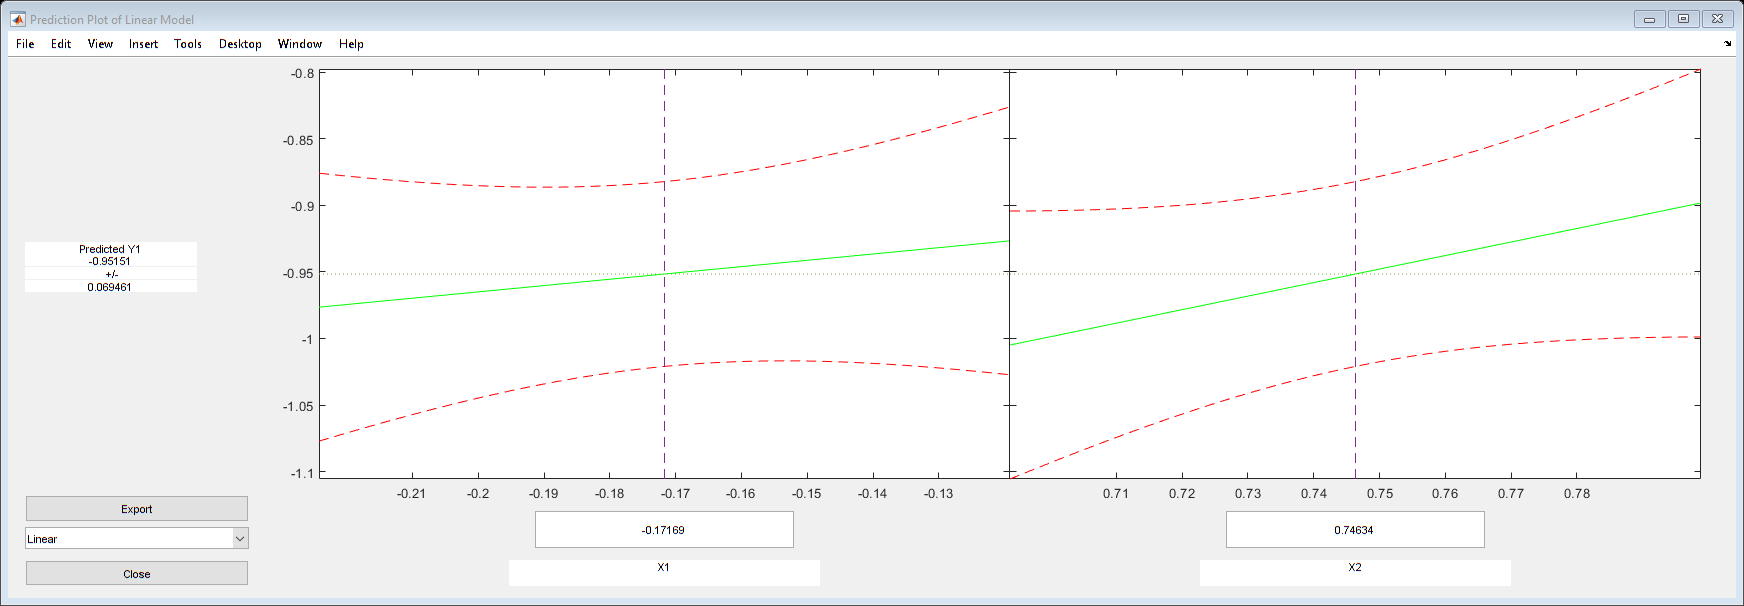

%now run rstool to get the sensitivity coefficients
rstool(input_values, Y, "linear");

The linear fit is in the follwing form


$$y=\beta_1 +\beta_2 x_1 +\beta_3 x_2$$


**From the above form the sensitivties are:**


$$\begin{array}{l}
S_{y,\mathrm{x1}} =\beta_2 =0\ldotp 4750\\
S_{y,\mathrm{x2}} =\beta_3 =1\ldotp 0171
\end{array}$$


Sy_x1 = beta1(2)

Sy_x1 = 0.4750

Sy_x2 = beta1(3)

Sy_x2 = 1.0171